#####################################################################################################################

# Pour executer ce script, cliquer sur la section à éxecuter, puis aller dans l'onglet "LIVE EDITOR" et cliquer sur "Run section", puis répéter pour chaque section lorsque vous avez fait les modifications nécéssaires

Quand vous avez généré un graphe, vous pouvez cliquer dessus, puis cliquer sur "open in figure window" (haut droite) pour pouvoir naviguer dedans  

Ce script est un exemple d'utilisation de matlab, à vous de le modifier pour obtenir les courbes désirées

#####################################################################################################################

% Initialisations

%Renommer le fichier selon le nom indiqué dans LabView
file = "filename001.txt";

% --> Vérifier que les 5 valeurs correspondent à l'ordre dans lequel est
%enregistré chaque courbe dans labView
time = 1;
current = 2;
voltage = 3;
power = 4;
charge = 5;
energy = 6;

%% import des données dans matlab

% --> le fichier de données doit etre dans le même dossier que ce script !!!
data = importdata(file);

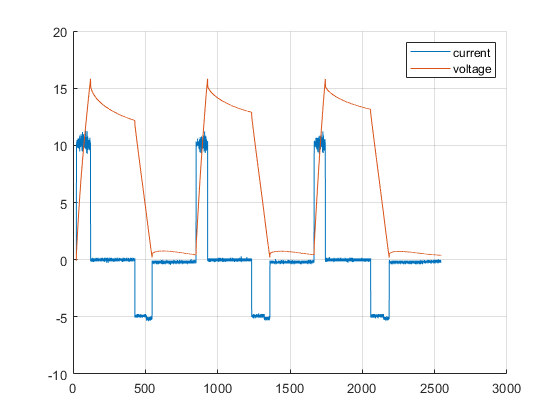

%% plot le courant et la tension sur une même figure
f1 = figure;
hold on
grid on
plot(data(:,time), data(:,current))
plot(data(:,time), data(:,voltage))
legend("current", "voltage")

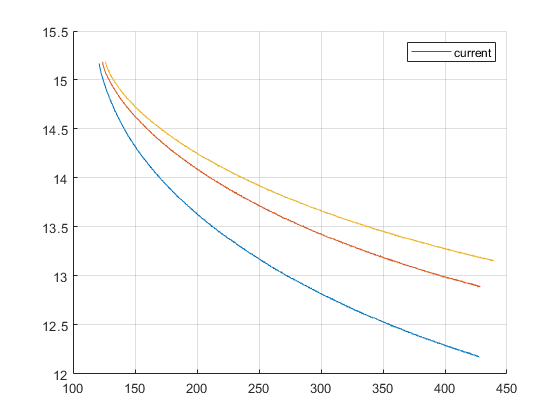

%% superpose deux courbes de tension prises à des moments différents
f2 = figure;
hold on
grid on

%  Valeurs à modifier à la main
debut1 = 984; % temps à partir duquel on veut afficher des données
fin1 = 4037; % temps de fin d'affichage des données
debut2 = 9051; 
fin2 = 12086;
debut3 = 17166; 
fin3 = 20290;
time_delay1 = 806.7; % décalage en temps de la deuxième courbe par rapport à la première
time_delay2 = 1618.2; % décalage en temps de la troisième courbe par rapport à la première


plot(data(debut1:fin1,time), data(debut1:fin1,voltage))
plot(data(debut2:fin2,time) - time_delay1, data(debut2:fin2,voltage))
plot(data(debut3:fin3,time) - time_delay2, data(debut3:fin3,voltage))

legend("current")

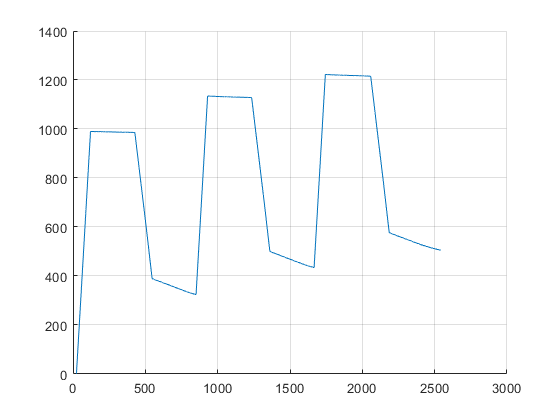

%% superpose deux courbes de tension prises à des moments différents
f3 = figure;
hold on
grid on

plot(data(:,time), data(:,charge))

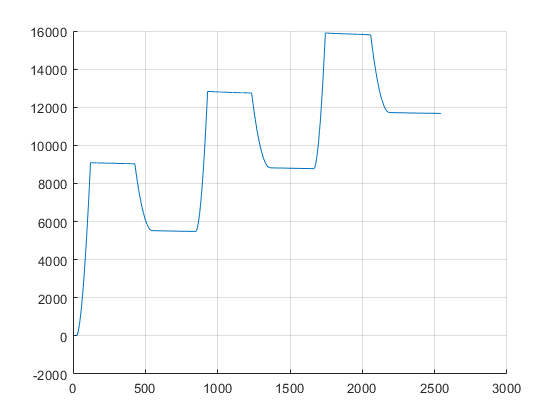

%% superpose deux courbes de tension prises à des moments différents
f4 = figure;
hold on
grid on

plot(data(:,time), data(:,energy))